load("wind_data_99.mat")
lats_scaled = (lats-37.5) / 11.5

lats_scaled = 1×93 single row vector
    1.0000    0.9783    0.9565    0.9348    0.9130    0.8913    0.8696    0.8478    0.8261    0.8043    0.7826    0.7609    0.7391    0.7174    0.6957    0.6739    0.6522    0.6304    0.6087    0.5870    0.5652    0.5435    0.5217    0.5000    0.4783    0.4565    0.4348    0.4130    0.3913    0.3696    0.3478    0.3261    0.3043    0.2826    0.2609    0.2391    0.2174    0.1957    0.1739    0.1522    0.1304    0.1087    0.0870    0.0652    0.0435    0.0217         0   -0.0217   -0.0435   -0.0652


alts_scaled = (alts-24200)/24200

alts_scaled =     1.0041    0.7826    0.6548    0.5002    0.4023    0.3008    0.1084   -0.0012   -0.1361   -0.2229   -0.3131   -0.3690   -0.4151   -0.4548   -0.4899   -0.5215   -0.5504   -0.6020   -0.6473   -0.6877   -0.7244   -0.7578   -0.7887   -0.8174   -0.8441   -0.8693   -0.8930   -0.9044   -0.9155   -0.9264   -0.9369   -0.9472   -0.9572   -0.9670   -0.9765   -0.9858   -0.9949


speeds_scaled = (speeds-7)/56

speeds_scaled =     0.6805    0.6855    0.6898    0.6943    0.6990    0.7039    0.7086    0.7133    0.7186    0.7239    0.7292    0.7346    0.7398    0.7453    0.7507    0.7568    0.7625    0.7681    0.7734    0.7786    0.7833    0.7878    0.7927    0.7978    0.8033    0.8089    0.8142    0.8195    0.8243    0.8297    0.8354    0.8413    0.8463    0.8516    0.8567    0.8619    0.8671    0.8719    0.8768    0.8817    0.8863    0.8909    0.8951    0.8994    0.9036    0.9083    0.9128    0.9173    0.9220    0.9259
    0.5027    0.5064    0.5102    0.5139    0.5172    0.5208    0.5243    0.5276    0.5314    0.5348    0.5377    0.5411    0.5447    0.5480    0.5516    0.5553    0.5593    0.5633    0.5679    0.5727    0.5772    0.5814    0.5854    0.5892    0.5930    0.5966    0.6001    0.6039    0.6071    0.6109    0.6149    0.6186    0.6229    0.6276    0.6317    0.6362    0.6407    0.6444    0.6483    0.6524    0.6561    0.6600    0.6641    0.6684    0.6728    0.6775    0.6821    0.6866   



alt_diff = diff(alts)

alt_diff = 	1.0e+03 *

   -5.3601   -3.0922   -3.7426   -2.3697   -2.4560   -4.6563   -2.6514   -3.2642   -2.1020   -2.1819   -1.3522   -1.1151   -0.9609   -0.8499   -0.7656   -0.6996   -1.2484   -1.0955   -0.9791   -0.8863   -0.8103   -0.7468   -0.6933   -0.6478   -0.6089   -0.5749   -0.2759   -0.2687   -0.2618   -0.2551   -0.2488   -0.2426   -0.2367   -0.2309   -0.2252   -0.2193


alt_diff_aug = [alt_diff(1) alt_diff alt_diff(end)]

alt_diff_aug = 	1.0e+03 *

   -5.3601   -5.3601   -3.0922   -3.7426   -2.3697   -2.4560   -4.6563   -2.6514   -3.2642   -2.1020   -2.1819   -1.3522   -1.1151   -0.9609   -0.8499   -0.7656   -0.6996   -1.2484   -1.0955   -0.9791   -0.8863   -0.8103   -0.7468   -0.6933   -0.6478   -0.6089   -0.5749   -0.2759   -0.2687   -0.2618   -0.2551   -0.2488   -0.2426   -0.2367   -0.2309   -0.2252   -0.2193   -0.2193


weights_1d = (alt_diff_aug(1:end-1)+alt_diff_aug(2:end))/2

weights_1d = 	1.0e+03 *

   -5.3601   -4.2261   -3.4174   -3.0562   -2.4129   -3.5562   -3.6539   -2.9578   -2.6831   -2.1419   -1.7670   -1.2337   -1.0380   -0.9054   -0.8078   -0.7326   -0.9740   -1.1719   -1.0373   -0.9327   -0.8483   -0.7785   -0.7200   -0.6705   -0.6283   -0.5919   -0.4254   -0.2723   -0.2652   -0.2585   -0.2520   -0.2457   -0.2397   -0.2338   -0.2280   -0.2222   -0.2193


weights_1d = weights_1d/mean(weights_1d)

weights_1d =     3.8761    3.0561    2.4713    2.2100    1.7448    2.5716    2.6423    2.1389    1.9403    1.5489    1.2778    0.8921    0.7506    0.6548    0.5841    0.5298    0.7043    0.8475    0.7501    0.6745    0.6134    0.5630    0.5207    0.4849    0.4544    0.4280    0.3076    0.1969    0.1918    0.1869    0.1822    0.1777    0.1733    0.1691    0.1649    0.1607    0.1586


% weights_1d = alts_scaled > -0.9
region_of_interest = alts > 10000 & alts < 40000

region_of_interest = 1×37 logical array
   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


true_weights = double(region_of_interest) + 1

true_weights =      1     1     1     2     2     2     2     2     2     2     2     2     2     2     2     2     2     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1



weights = repmat(double(weights_1d),[93, 1])'

weights =     3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761    3.8761
    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.0561    3.056

Run the fits:

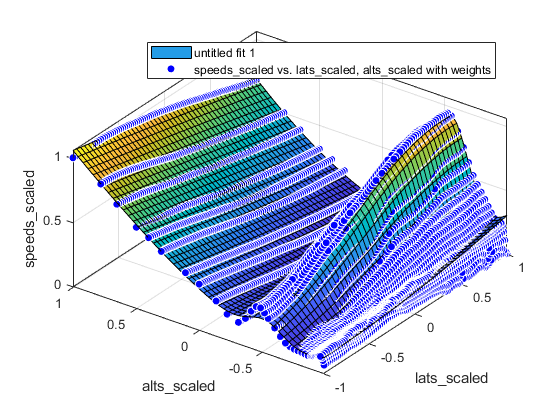

     General model:
     fit(l,a) = c0 + cql * (l-lqc)^2 + cqa * (a-aqc)^2 + cqla * a * l + cg * 
                    exp(-(abs(l-lgc)^lgh/(2*lgs^2)+abs(a-agc)^agh/(2*ags^2)
                    +cgc*a*l)) + c4a * (a-c4c)^4 + c12 * l * a^2 +c21 * 
                    l^2 * a
     Coefficients (with 95% confidence bounds):
       agc =     -0.5363  (-0.5379, -0.5348)
       agh =       1.957  (1.902, 2.012)
       ags =      0.1459  (0.1384, 0.1533)
       aqc =      -1.465  (-2.691, -0.2382)
       c0 =      -0.517  (-1.053, 0.01898)
       c12 =     0.08495  (0.07893, 0.09098)
       c21 =     -0.0252  (-0.03203, -0.01838)
       c4a =     0.02259  (-0.003347, 0.04852)
       c4c =       1.028  (0.006922, 2.049)
       cg =      0.8051  (0.7647, 0.8454)
       cgc =      0.2787  (0.157, 0.4003)
       cqa =      0.1866  (0.08782, 0.2854)
       cql =     0.01651  (0.01223, 0.0208)
       cqla =     -0.1362  (-0.1407, -0.1317)
       lgc =      0.6944  (0.6202, 0.7686)
       lgh =     

fit=createFit(lats_scaled, alts_scaled, speeds_scaled, weights)

Make Python code:

names = coeffnames(fit)

names = 18×1 cell array
    {'agc' }
    {'agh' }
    {'ags' }
    {'aqc' }
    {'c0'  }
    {'c12' }
    {'c21' }
    {'c4a' }
    {'c4c' }
    {'cg'  }
    {'cgc' }
    {'cqa' }
    {'cql' }
    {'cqla'}
    {'lgc' }
    {'lgh' }
    {'lgs' }
    {'lqc' }

vals = coeffvalues(fit)

vals =    -0.5363    1.9570    0.1459   -1.4645   -0.5170    0.0850   -0.0252    0.0226    1.0282    0.8051    0.2787    0.1866    0.0165   -0.1362    0.6944    2.0777    0.9806    4.0357


for i=1:length(names)
    disp(sprintf("%s = %.16f", names{i}, vals(i)))
end

agc = -0.5363486000267786
agh = 1.9569754777072828
ags = 0.1458701999734713
aqc = -1.4645014948089652
c0 = -0.5169694086686631
c12 = 0.0849519807021402
c21 = -0.0252010113059998
c4a = 0.0225856848053377
c4c = 1.0281877353734501
cg = 0.8050736230004489
cgc = 0.2786691793571486
cqa = 0.1866078047914259
cql = 0.0165126852561671
cqla = -0.1361667658248024
lgc = 0.6943655538727291
lgh = 2.0777449841036777
lgs = 0.9805766577269118
lqc = 4.0356834595743214


f=strrep(formula(fit),"^"," ** ");

c0 + cql * (l-lqc) ** 2 + cqa * (a-aqc) ** 2 + cqla * a * l + cg * exp(-(abs(l-lgc) ** lgh/(2*lgs ** 2)+abs(a-agc) ** agh/(2*ags ** 2)+cgc*a*l)) + c4a * (a-c4c) ** 4 + c12 * l * a ** 2 +c21 * l ** 2 * a


f=strrep(f, "l")
disp(f)